**FIS tipo I**

fis1 = sugfis;
fis1 = addInput(fis1,[-1 1],'Name','E');
fis1 = addInput(fis1,[-1 1],'Name','delE');
fis1 = addMF(fis1,'E','trimf',[-2 -1 0],'Name','N');
fis1 = addMF(fis1,'E','trimf',[-1 0 1],'Name','Z');
fis1 = addMF(fis1,'E','trimf',[0 1 2],'Name','P');
fis1 = addMF(fis1,'delE','trimf',[-2 -1 0],'Name','N');
fis1 = addMF(fis1,'delE','trimf',[-1 0 1],'Name','Z');
fis1 = addMF(fis1,'delE','trimf',[0 1 2],'Name','P');

**FIS utilizando funciones de membresía tipo-II**

fis2 = convertToType2(fis1);
scale = [0.2 0.9 0.2;0.3 0.9 0.3];
for i = 1:length(fis2.Inputs)
    for j = 1:length(fis2.Inputs(i).MembershipFunctions)
        fis2.Inputs(i).MembershipFunctions(j).LowerLag = 0;
        fis2.Inputs(i).MembershipFunctions(j).LowerScale = scale(i,j);
    end
end

Plot

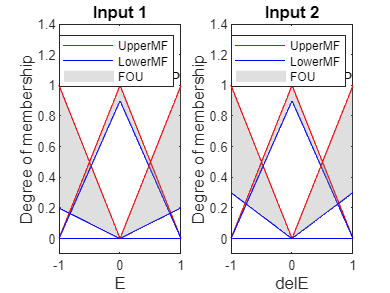

figure
subplot(1,2,1)
plotmf(fis2,'input',1)
title('Input 1')
subplot(1,2,2)
plotmf(fis2,'input',2)
title('Input 2')